Problem 1

clear; clc  

(a)

The delayed system with RHP zero:

s = tf('s');
T_d = 5*10^-3;
G = (-s+3)/(s+2)/(s+1000)*exp(-T_d*s);

Use inverse-based loop shaping to design controller. The basic loop shape of $\frac{s+a\omega_c}{s^2(s+b\omega_c)}$ will create at least -90 deg's phase lag at crossover frequency. In order to have 40 deg's PM, the phase lag caused by time delay and RHP zero should be at most -50 deg.

Therefore, the crossover frequency has a upper bound:


$$-2\tan^{-1}(\frac{\omega_c}{3})>-50\deg \Rightarrow \omega_c <1.4 rad/s$$


Assume $\begin{cases}
a = \frac{1}{\alpha} \\
b = \alpha
\end{cases}$, and tune $\omega_c \;$and $\alpha$ to meet specifications.

w_c = 1.4;  % start with theoretical UB
while true
    alpha = 10^4;  % start with large enough alpha
    alpha_left = 0;
    alpha_right = alpha;
    a = 1/alpha;
    b = alpha;
    L = (s+a*w_c)/(s+b*w_c)/s^2*(-s+3)/(s+3)*exp(-T_d*s);
    [mag,~] = bode(L,w_c);
    L = 1/mag*L;
    [GM,PM] = margin(L);
    if db(GM)<6 || PM<40  % decrease wc if large alpha can't meet
        w_c = w_c-0.01;
    else
        while true  % bisect alpha 
            alpha_old = alpha;
            alpha = (alpha_left+alpha_right)/2;
            a = 1/alpha;
            b = alpha;
            L = (s+a*w_c)/(s+b*w_c)/s^2*(-s+3)/(s+3)*exp(-T_d*s);
            [mag,~] = bode(L,w_c);
            L = 1/mag*L;
            [GM,PM] = margin(L);
            if abs(alpha-alpha_old) < 1e-6
                break
            elseif abs(db(GM))>=6 && PM>=40
                alpha_right = alpha;
            else
                alpha_left = alpha;
            end
        end
        break
    end
end

The maximized crossover frequency:

w_c

w_c = 1.3800

The designed controller:

[a*w_c;b*w_c]

ans =     0.0024
  791.4777



$$K = \frac{(s+a\omega_c)(s+2)(s+1000)}{s^2(s+b\omega_c)(s+3)}=\frac{(s+0.0024)(s+2)(s+1000)}{s^2(s+791.5)(s+3)}$$


The final achieved loop shape and stability margin:

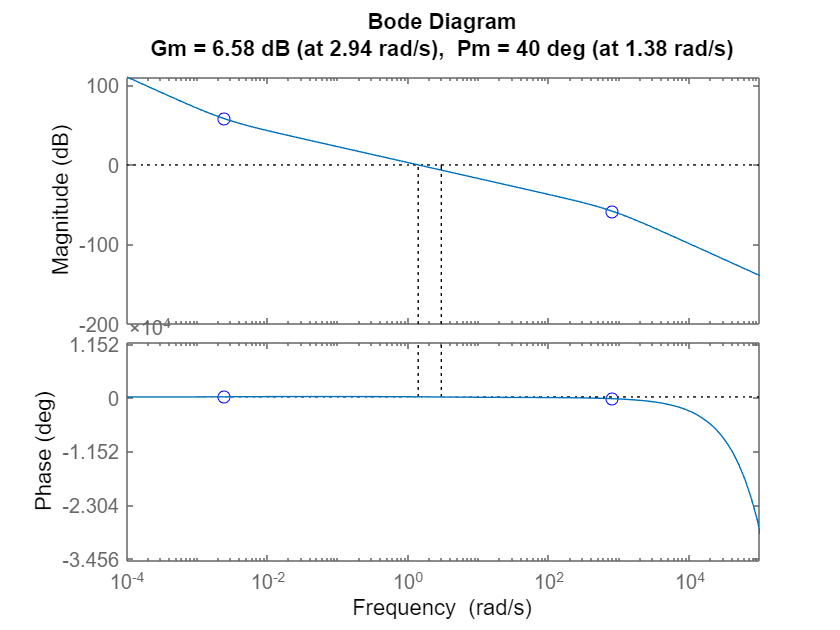

bode(L,[a*w_c,b*w_c],'o')
hold on
margin(L);
hold off

Sensitivity function:

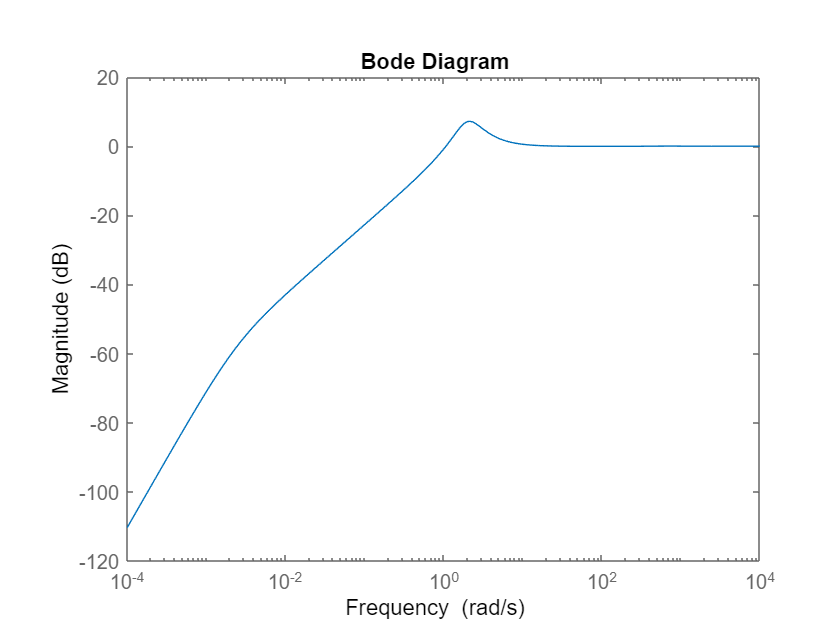

S = 1/(1+L);
bodemag(S);

(b)

For a unstable system without time delay:

clear;clc
s = tf('s');
G = (s+5)/(-s+1)/(s+1000);

Use Loopsyn to design the controller, and start with a relatively high frequency of 2 kHz:

w_c = 2000;
G_d = w_c/s;
[K,CL,GAM] = loopsyn(G,G_d);

The designed open-loop shape w.r.t desired upper bound and lower bound:

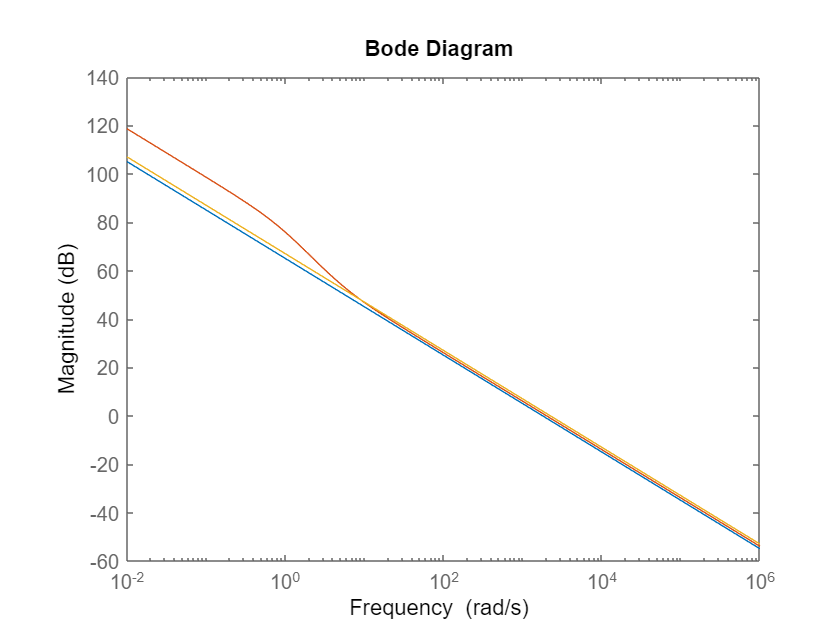

bodemag(G_d/GAM,G*K,G_d*GAM);

Check margins to see if specs are met:

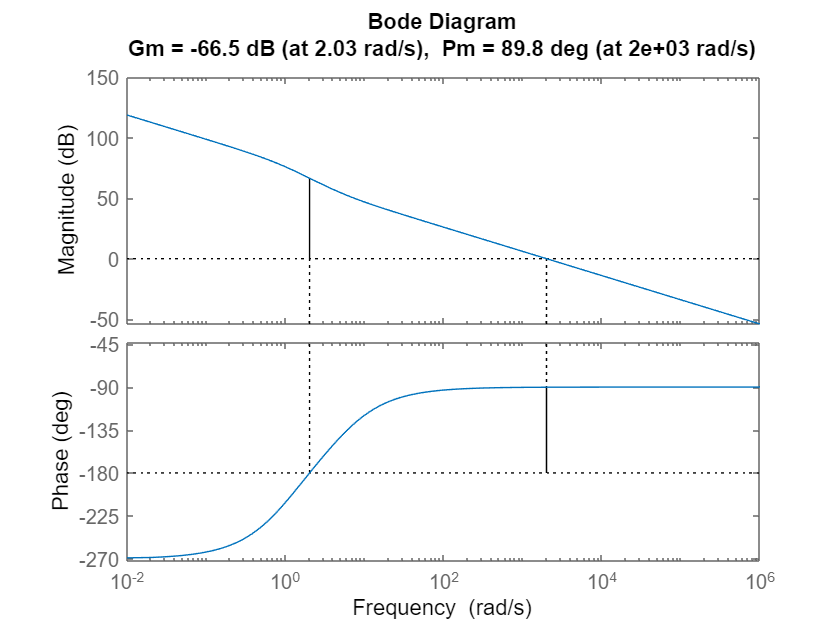

L = G*K;
margin(L);

Since the plant is unstable, the absolute value of GM satisfies the specs.

isStable = isstable(feedback(L,1))

isStable = logical
   1


As demonstrated, the closed-loop system is stable.

Problem 2

(a)

clear;clc

Input the HDD model:

HDDModel;
s = tf('s');

The desired performance weight shape:

M = 2;  % 6dB
A = 0.001;  % -60dB
BWp = 3*10^3*2*pi;  % 3kHz
Wp_1 = makeweight(1/A,BWp,1/M);
Wp_2 = (s/sqrt(M)+BWp)^2/(s+BWp*sqrt(A))^2;

Design the controller with performance sensitivity weights:

[K_1,CL_1,GAM_1] = mixsyn(P,Wp_1,[],[]);
[K_2,CL_2,GAM_2] = mixsyn(P,Wp_2,[],[]);

The sensitivity function and desired sensitivity function using first-order method:

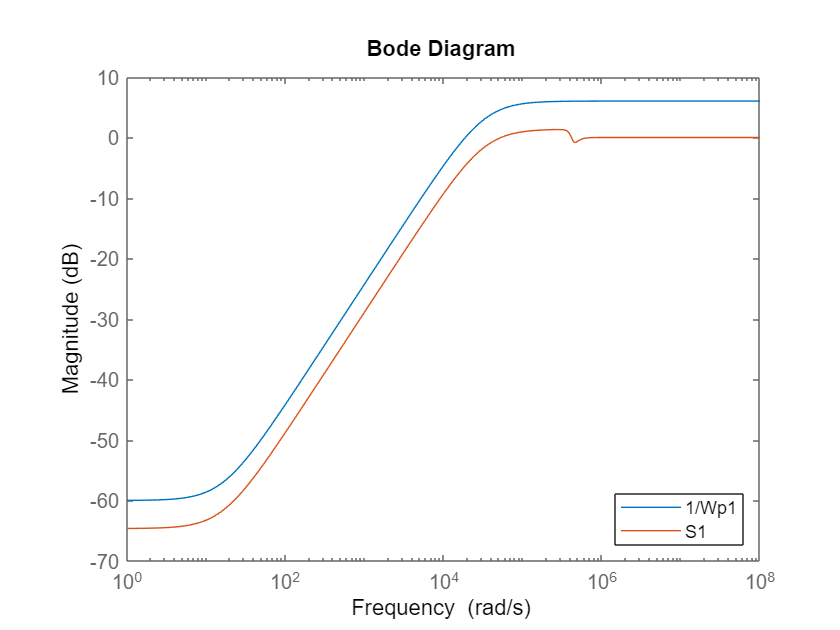

S_1 = 1/(1+P*K_1);
T_1 = 1-S_1;
bodemag(1/Wp_1,S_1);
legend('1/Wp1','S1','location','southeast')

The sensitivity function and desired sensitivity function using second-order method:

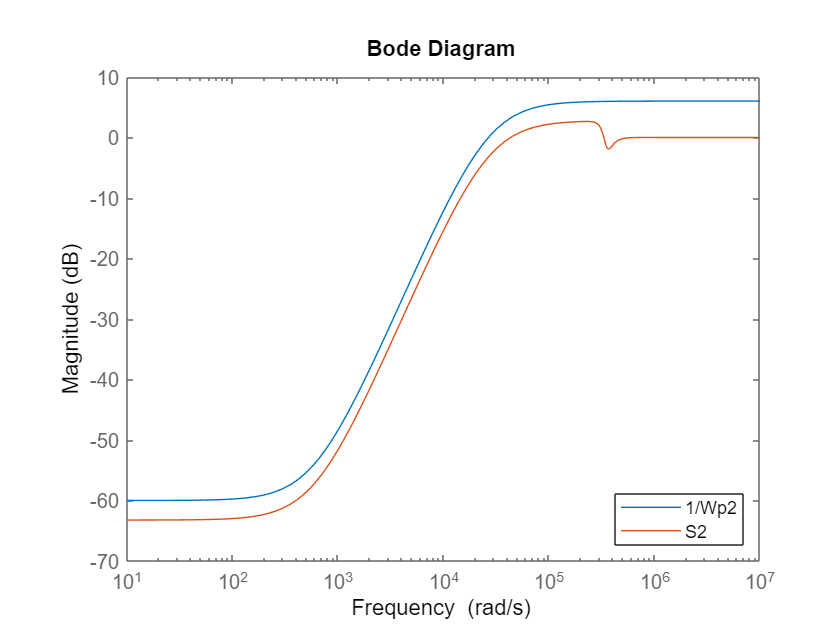

S_2 = 1/(1+P*K_2);
T_2 = 1-S_2;
bodemag(1/Wp_2,S_2);
legend('1/Wp2','S2','location','southeast')

Step response of both first-order and second-order methods design:

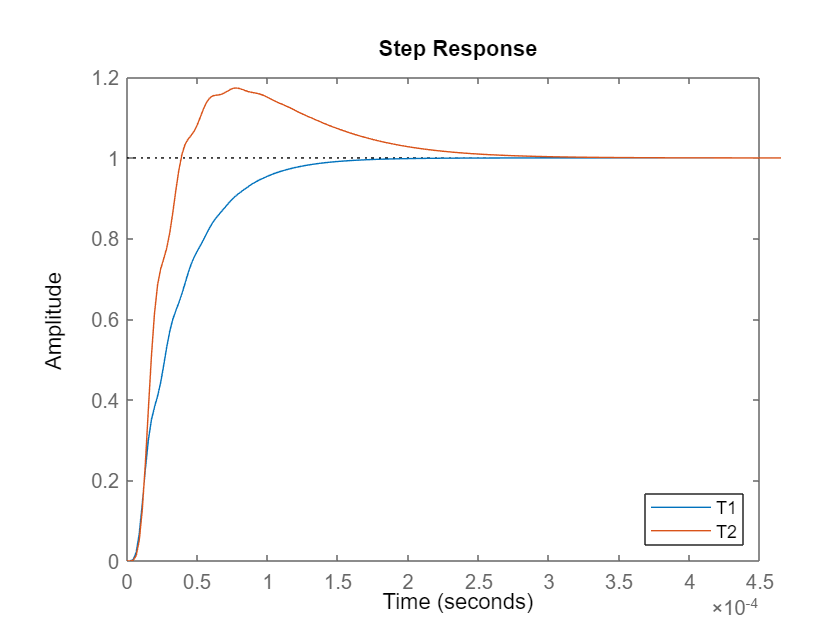

step(T_1,T_2);
legend('T1','T2','location','southeast')

The sensitivity crossing frequency will have a maximum boundary. 

(b)

The desired complementary sensitivity weight (already tuned to meet GAM_pt < 1):

Mt = sqrt(2);  % 3dB
At = 0.5;
BWt = 10^4*2*pi;  % 10kHz
Wt = makeweight(1/Mt,BWt,1/At);  % 20dB/dec

Design the controller with performance sensitivity and complementary sensitivity weights:

[K_pt,CL_pt,GAM_pt] = mixsyn(P,Wp_2,[],Wt);  % order matters

Check that $\frac{1}{W_P}+\frac{1}{W_T} \geq 1$: 

weightbound = 1/norm(1/(1/Wp_2+1/Wt), 'inf')

weightbound = 1.1499

The sensitivity function and sensitivity weight function:

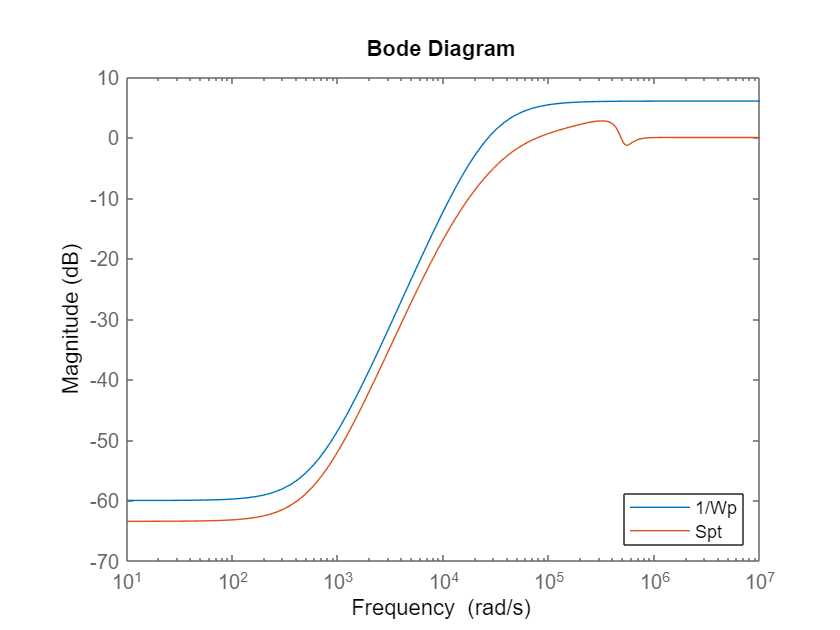

S_pt = 1/(1+P*K_pt);
bodemag(1/Wp_2,S_pt);
legend('1/Wp','Spt','location','southeast')

The complementary sensitivity function and complementary sensitivity weight function:

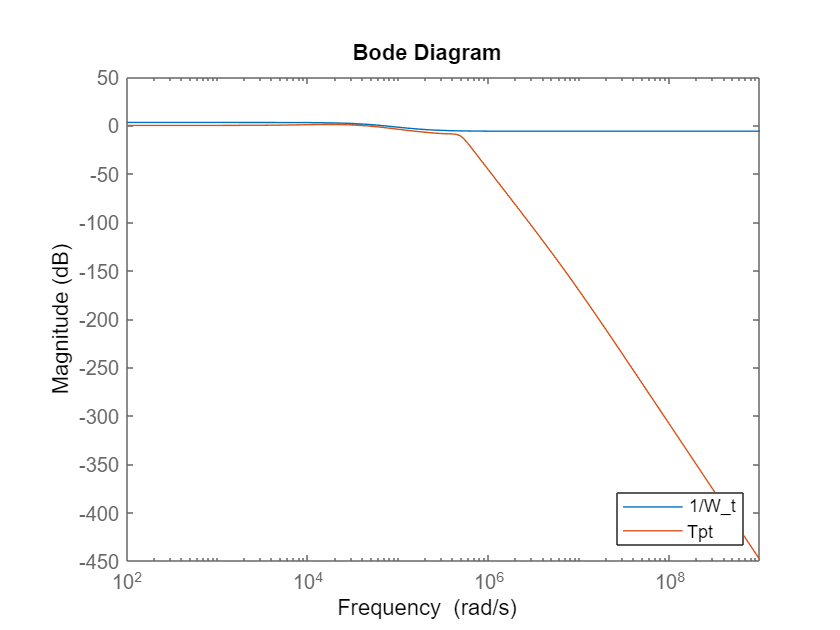

T_pt = 1-S_pt;
bodemag(1/Wt,T_pt);
legend('1/W_t','Tpt','location','southeast')

(c) 

Include control weight:

Wu = 1/100;

Use iteration method to achieve GAM < 1:

BW_right = 10^8*2*pi; 
BW_left = 0;
Wp = 0;
Wt = 0;
GAM_ms = 0;
while true
    GAM_old = GAM_ms;
    BW = (BW_left+BW_right)/2;
    Wp = (makeweight(sqrt(1/A),BW,sqrt(1/M)))^2;
    Wt = makeweight(1/Mt,5*BW,1/At);
    [K_ms,CL_ms,GAM_ms] = mixsyn(P,Wp,Wu,Wt);
    if abs(GAM_ms-GAM_old)<1e-6
        break
    elseif GAM_ms<1
        BW_left = BW;  
    else
        BW_right = BW;
    end
end

The system sensitivity function and complementary sensitivity function:

L_ms = P*K_ms;
S_ms = 1/(1+L_ms);
T_ms = 1-S_ms;

The sensitivity function and sensitivity weight function:

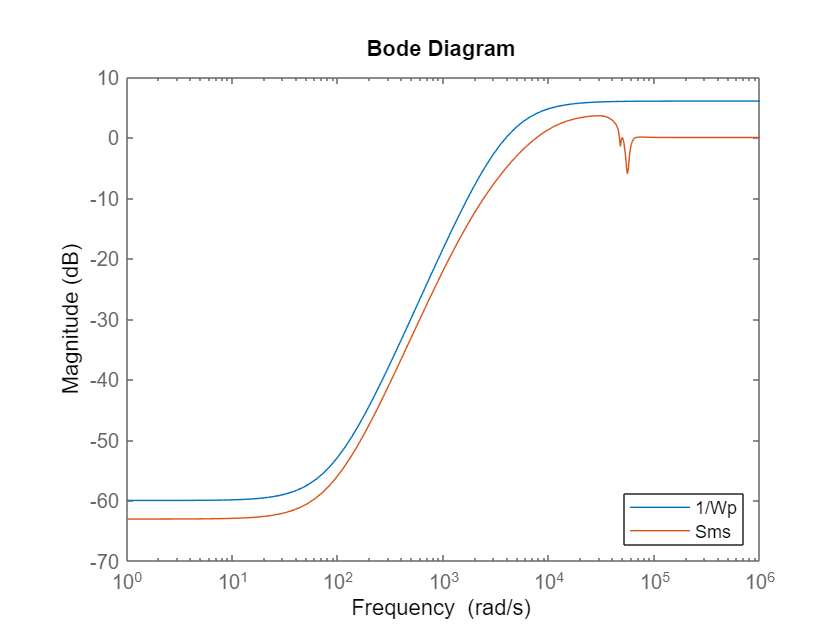

bodemag(1/Wp,S_ms);
legend('1/Wp','Sms','location','southeast')

The control function and control weight function:

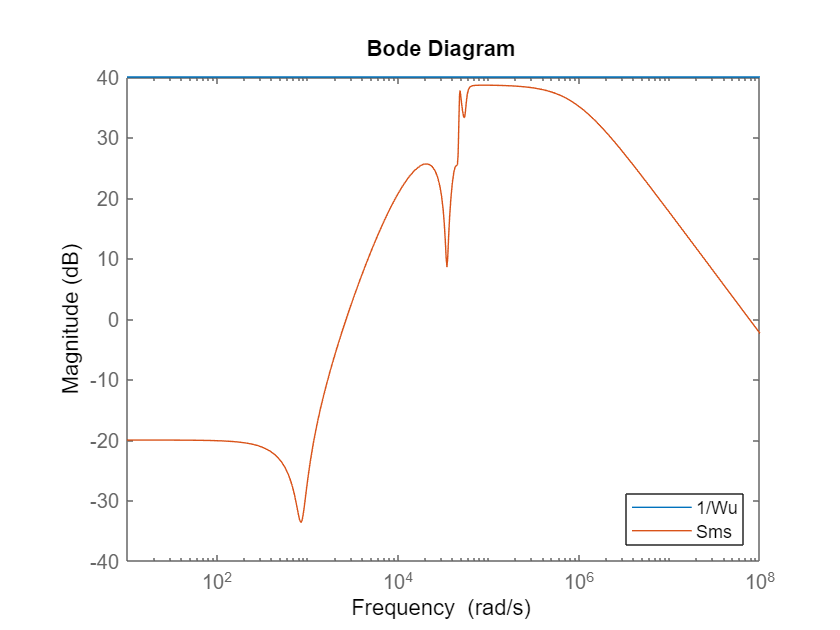

bodemag(tf(1/Wu,1),K_ms*S_ms);
legend('1/Wu','Sms','location','southeast')

The complementary sensitivity function and complementary sensitivity weight function:

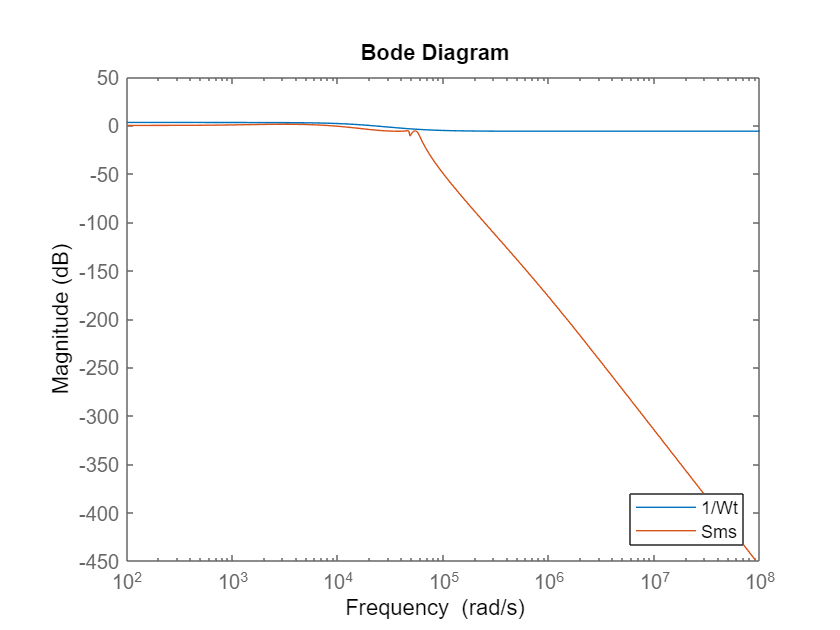

bodemag(1/Wt,T_ms);
legend('1/Wt','Sms','location','southeast')

The final $H_{\infty}$ norm:

N = [Wp*S_ms;Wu*K_ms*S_ms;Wt*T_ms];
H_inf_N = norm(N,'inf')

H_inf_N = 3.1614

H_inf_CL = norm(CL_ms,'inf')

H_inf_CL = 0.9966

% H_inf_p = norm(Wp*S_ms,'inf')
% H_inf_u = norm(Wu*K_ms*S_ms,'inf')
% H_inf_t = norm(Wt*T_ms,'inf')

No idea why they have different values...

But the closed-loop system is stable with the designed controller:

isStable = isstable(feedback(K_ms*P,1))

isStable = logical
   1


Problem 3

clear; clc

(a)

Input dual-stage HDD model:

HDDModel_DS;
s = tf('s');

Stack seperate TFs to get DISO system TF matrix:


$$y = \left[ \matrix{VCM&PZT}\right]\left[ \matrix{u_{VCM}\cr u_{PZT}}\right]$$


G = [VCM,PZT];

DISO system Bode plots:

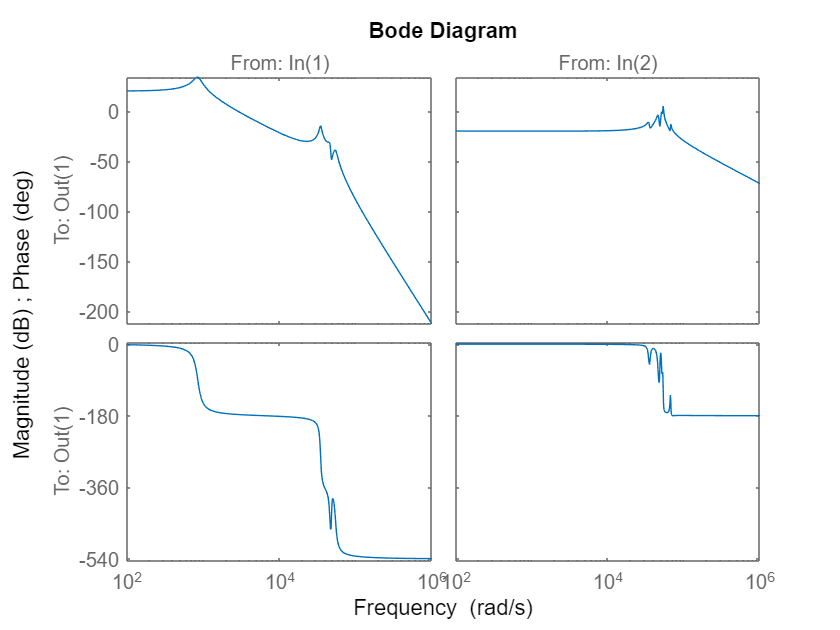

bode(G);

(b)

Actuator saturations:

Wu_vcm = 1/100;
Wu_pzt = 1/10;

Same specs from previous question:

M = 2;  % 6dB
A = 0.001;  % -60dB
Mt = sqrt(2);  % 3dB
At = 0.5;

Use iteration method to achieve GAM < 1:

BW_right = 10^8*2*pi; 
BW_left = 0;
Wp = 0;
Wt = 0;
Wu = [Wu_vcm,0;0,Wu_pzt];
GAM_ms = 0;
while true
    GAM_old = GAM_ms;
    BW = (BW_left+BW_right)/2;
    Wp = (makeweight(sqrt(1/A),BW,sqrt(1/M)))^2;
    Wt = makeweight(1/Mt,5*BW,1/At);
    [K_ms,CL_ms,GAM_ms] = mixsyn(G,Wp,Wu,Wt);
    if abs(GAM_ms-GAM_old)<1e-4
        break
    elseif GAM_ms<1
        BW_left = BW;  
    else
        BW_right = BW;
    end
end

The system sensitivity function and complementary sensitivity function:

L_ms = G*K_ms;
S_ms = eye/(eye+L_ms);
T_ms = eye-S_ms;

The sensitivity function and sensitivity weight function:

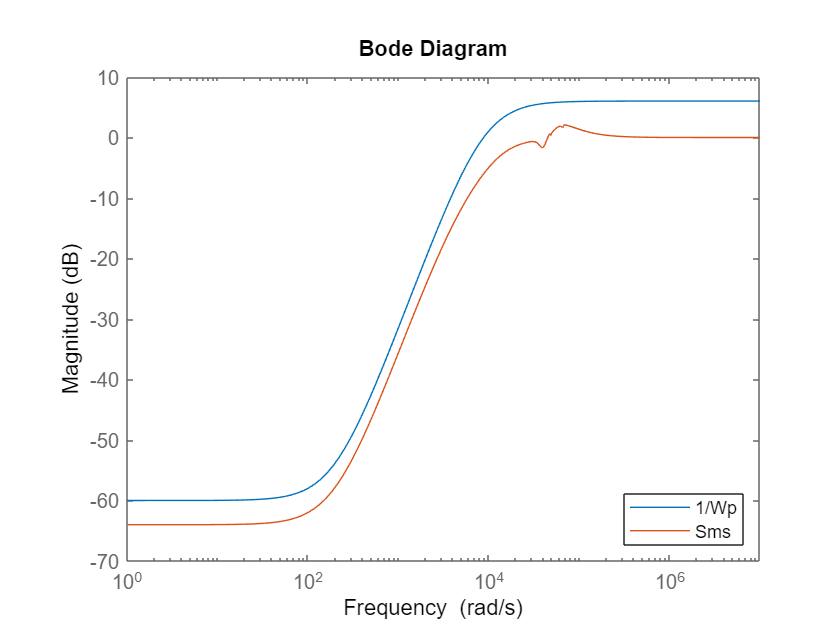

bodemag(1/Wp,S_ms);
legend('1/Wp','Sms','location','southeast')

The mags of $W_UKS$ are below 0 dB:

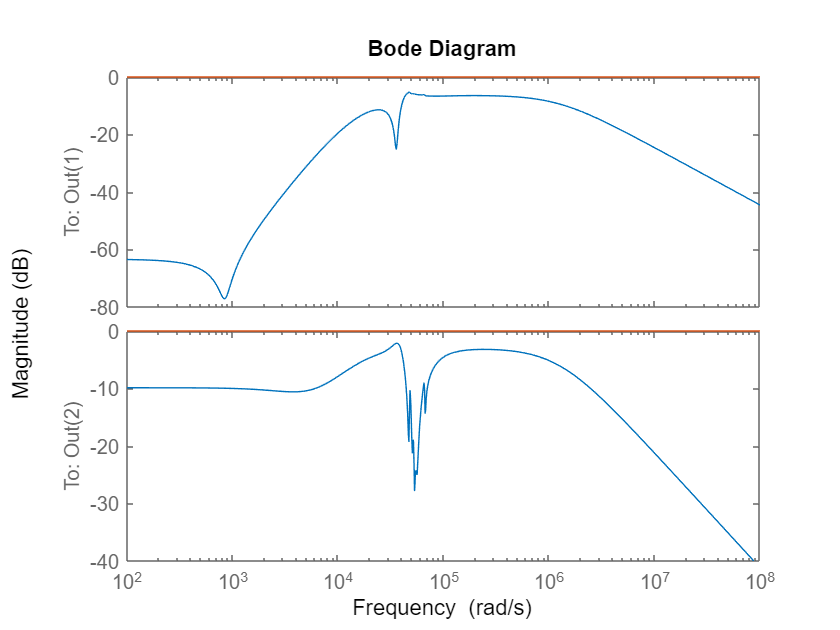

bodemag(Wu*K_ms*S_ms,[tf(1,1);tf(1,1)]);